% %Ahmad's Code
% if not(libisloaded('wsprsim'))
%    loadlibrary('wsprsim')
% end
% insig = libpointer('doublePtr', zeros(1,45000));
% qdsig = libpointer('doublePtr', zeros(1,45000));
% calllib('wsprsim', 'wsprfunc','VE3EMB FN25 30', 50, insig, qdsig)
% I= insig.val;
% Q=qdsig.val;

signal found in transmitter converted to wav

[y,fs]= audioread('209_45002.wav');

signal produced by my code

[y2,fs2]= audioread('209_4500.wav');

plot each signal 

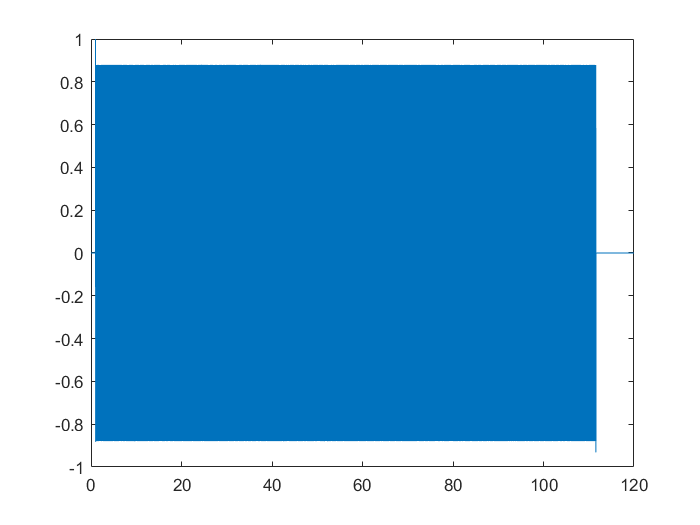

dt=1/fs;
dt2=1/fs2;
t=0:dt:(length(y)-1)/fs;
t2=0:dt2:(length(y2)-1)/fs2;
plot(t,y);

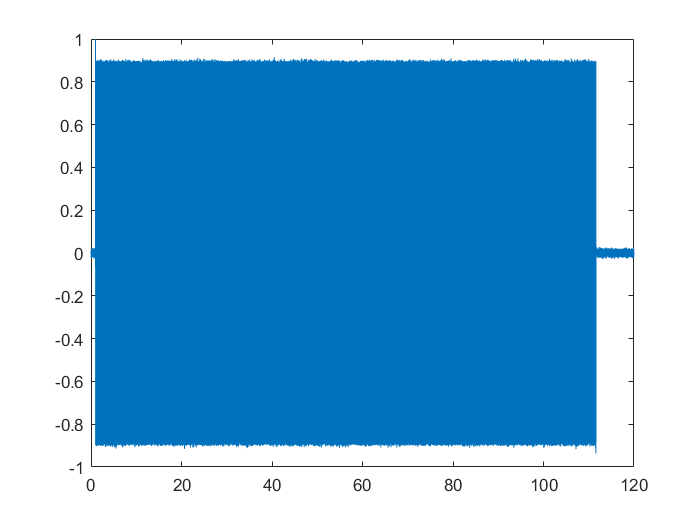

plot(t2,y2);

plot spectrogram

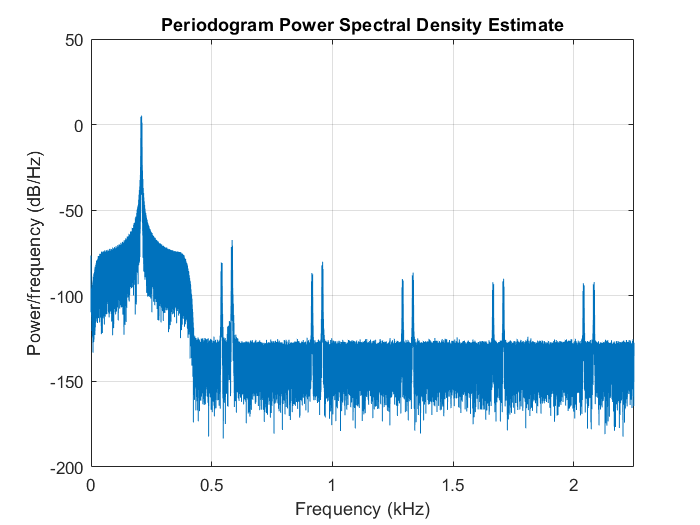

plot(psd(spectrum.periodogram,y,'Fs',fs,'NFFT',length(y)));

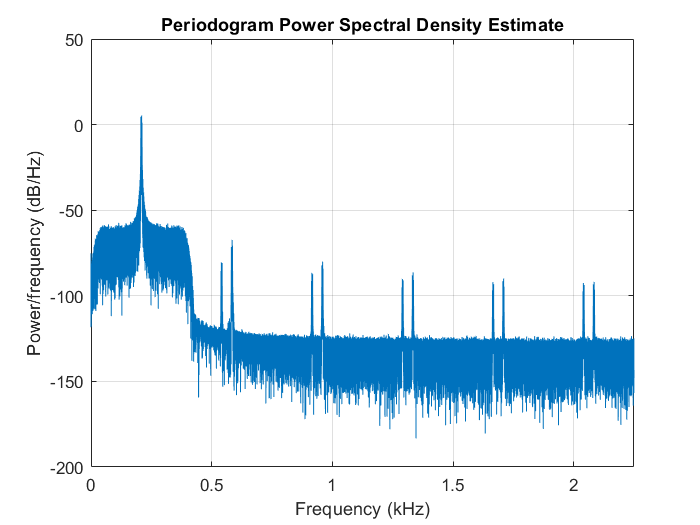

plot(psd(spectrum.periodogram,y2,'Fs',fs2,'NFFT',length(y2)));

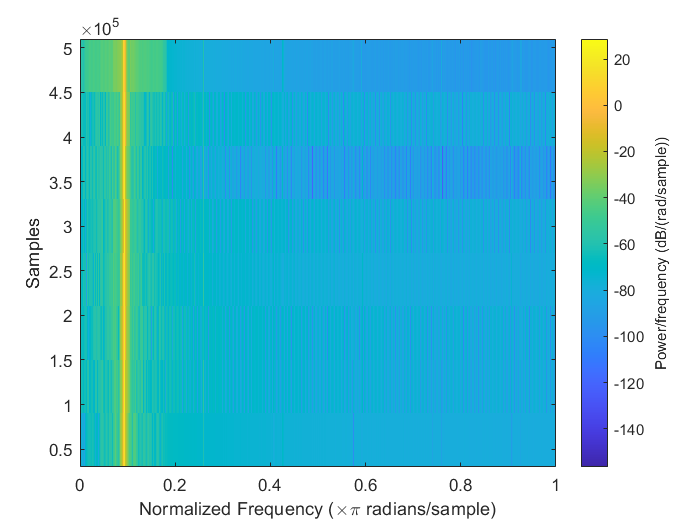

spectrogram(y);

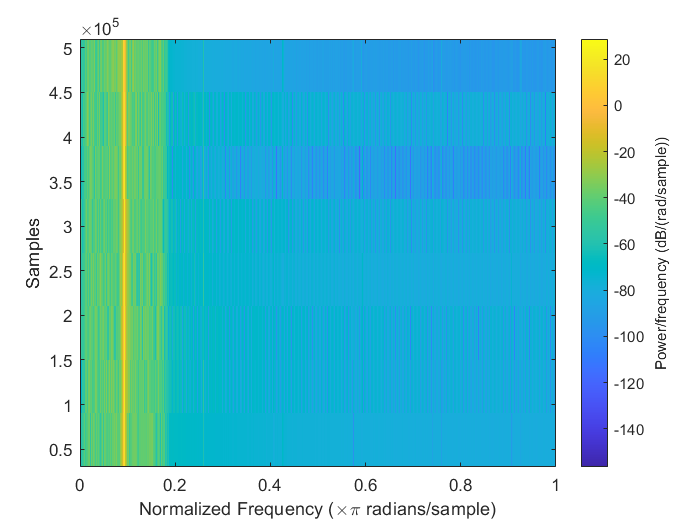

spectrogram(y2);

correlate the two

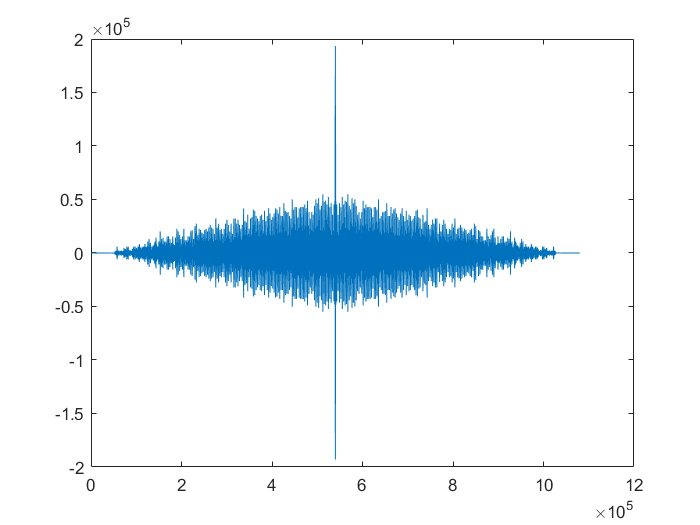

corr = xcorr(y,y2);
plot(corr);

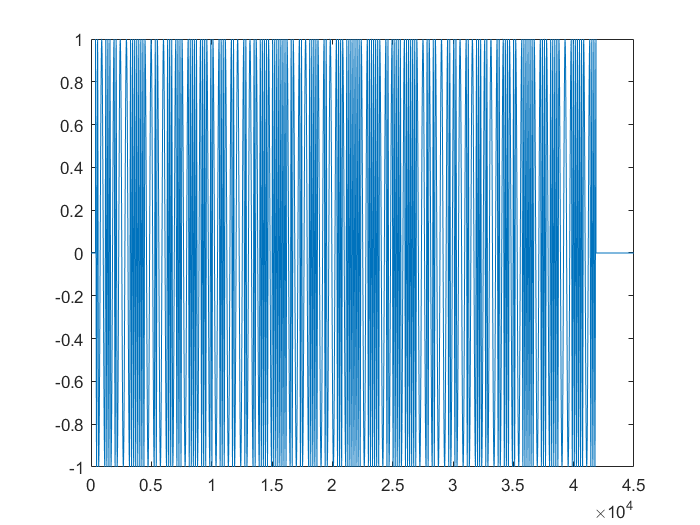

if not(libisloaded('wsprsim'))
   loadlibrary('wsprsim')
end
insig = libpointer('doublePtr', zeros(1,45000));
qdsig = libpointer('doublePtr', zeros(1,45000));
calllib('wsprsim', 'wsprfunc','VE3EMB FN25 30', 50, insig, qdsig)

plot(insig.val);

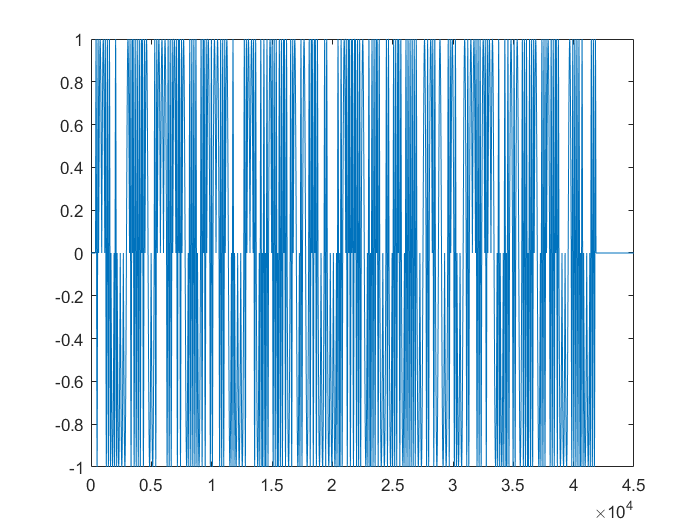

plot(qdsig.val);

FileName = 'test.c2'; % no noise OK
fileID = fopen(FileName,'r');

The following three parameters (file name, type and frequency) are read, but not interpreted.

% read file name (14 characters)
fname=fread(fileID,[1 14],'char');
% read WSPR type (integer) 2="two minute mode"
type=fread(fileID,[1 1],'int');
% read frequency (double)
dfreq=fread(fileID,[1 1],'double');

The content of the file represents 120 seconds of signal samples that have been buffered, termed the *two minute mode*.  The sampling rate ($f_s$) is 375 samples per second (sps).  Hence there are $n=375 \cdot 120=45,000$ complex samples (in-phase and quadrature) read. Let $x_0 ,x_1 ,\ldotp \ldotp \ldotp ,x_{n-1}$ represent the discrete complex samples of two-minute channel data.

n=45000; % number of sambles (120 seconds of channel data)
fs=375; % sampling frequency
% read data (float)
buffer=fread(fileID,[2 n],'float');
% close the ".c2" file
fclose(fileID);

% in-phase
I=buffer(1,:);
% quadrature
Q=buffer(2,:);
 plot(I);

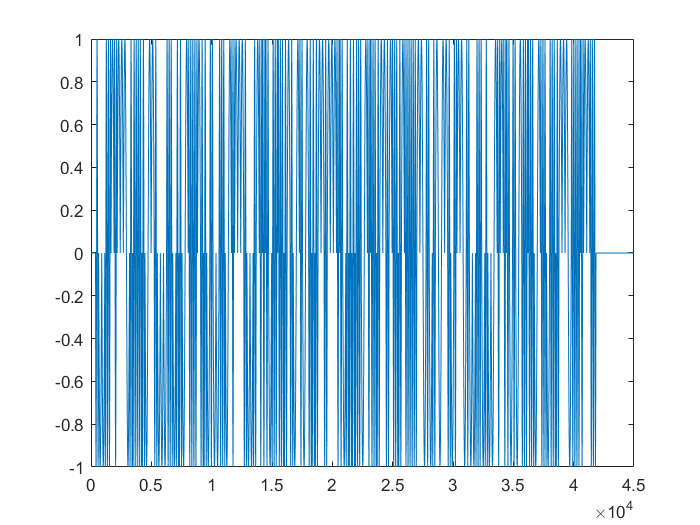

 plot(Q);

plot  inphase signals  in one figure

plot(I)
hold

Current plot held


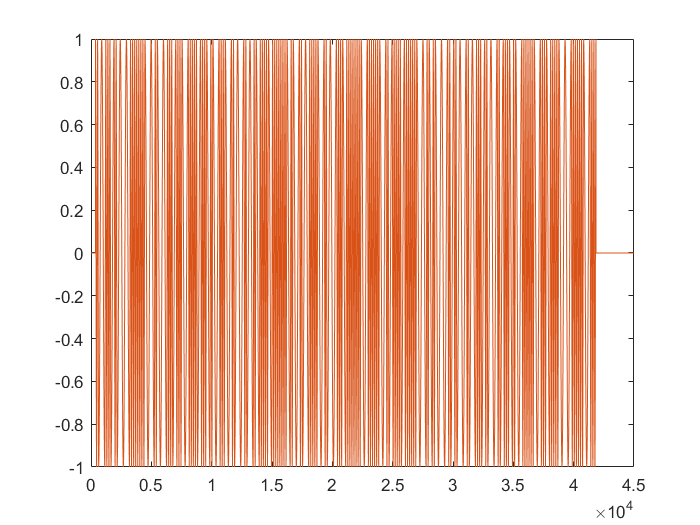

plot(insig.val)

compare  quadrature with flipping the one coming from my code

figure
plot(Q)
hold

Current plot held


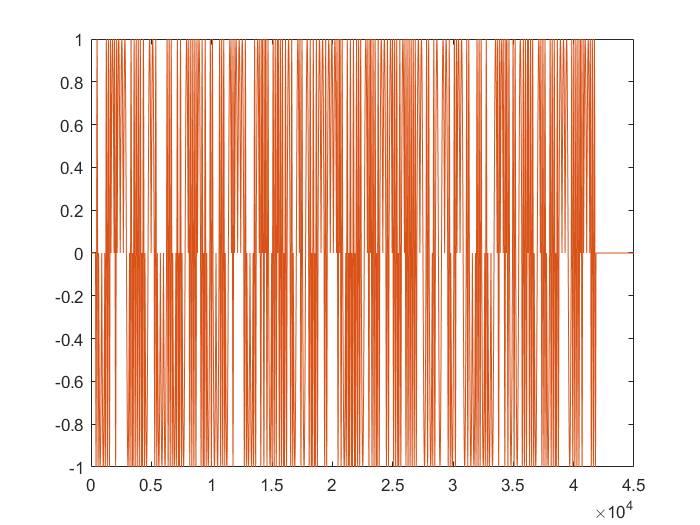

plot(-qdsig.val)

figure

FileName = '000000_0001.c2'; % no noise OK
fileID = fopen(FileName,'r');

The following three parameters (file name, type and frequency) are read, but not interpreted.

% read file name (14 characters)
fname=fread(fileID,[1 14],'char');
% read WSPR type (integer) 2="two minute mode"
type=fread(fileID,[1 1],'int');
% read frequency (double)
dfreq=fread(fileID,[1 1],'double');

The content of the file represents 120 seconds of signal samples that have been buffered, termed the *two minute mode*.  The sampling rate ($f_s$) is 375 samples per second (sps).  Hence there are $n=375 \cdot 120=45,000$ complex samples (in-phase and quadrature) read. Let $x_0 ,x_1 ,\ldotp \ldotp \ldotp ,x_{n-1}$ represent the discrete complex samples of two-minute channel data.

n=45000; % number of sambles (120 seconds of channel data)
fs=375; % sampling frequency
% read data (float)
buffer=fread(fileID,[2 n],'float');
% close the ".c2" file
fclose(fileID);

% in-phase
I=buffer(1,:);
% quadrature
Q=buffer(2,:);
 plot(I);

 plot(Q);

in the writec2file in wsprsim the quadrature is being written as -q